x=[3.6 7.7 9.3 4.1 8.6 2.8 1.3 7.9 10.0 5.4];
y=[16.5 150.6 263.1 24.7 208.5 9.9 2.7 163.9 325.0 54.3];
x0=[0.3,0.4,0.1];
[result,resnorm,residual]=lsqcurvefit(@fuction_1,x0,x,y)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


result =     0.2269    0.3385    0.3022


resnorm = 6.2950

residual =     0.3880    1.1291   -0.3964   -0.3383    0.7148   -1.3749   -1.3265   -0.4290   -0.3436   -0.3674


sum(residual.^2)

ans = 6.2950

x=normrnd(0,0.1,[1000,1]);
[muhat,sigmahat,muci,sigmaci]=normfit(x)

muhat = 0.0038

sigmahat = 0.1005

muci =    -0.0024
    0.0101


sigmaci =     0.0963
    0.1052


x=[59.6 55.2 56.6 55.8 60.2 57.4 59.8 56.0 55.8 57.4 56.8 54.4 59.0 57.0 56.0 60.0 58.2 59.6 59.2 53.8]

x =    59.6000   55.2000   56.6000   55.8000   60.2000   57.4000   59.8000   56.0000   55.8000   57.4000   56.8000   54.4000   59.0000   57.0000   56.0000   60.0000   58.2000   59.6000   59.2000   53.8000


[mu,sigma,muCrange,sigmaCrange]=normfit(x,0.05)

mu = 57.3900

sigma = 1.9665

muCrange =    56.4696
   58.3104


sigmaCrange =     1.4955
    2.8723


[p,q]=mle('norm',x)

p =    57.3900    1.9167


q =    56.4696    1.4955
   58.3104    2.8723


simahat=moment(x,2)

simahat = 3.6739

a=[1,2,3,4;4,5,6,7];
max(a,[],1)

ans =      4     5     6     7


ans = 4

syms a b
f=sqrt(a)+b;
f=subs(f,[a b],[2 1])

$$f = \sqrt{2}+1$$

class(vpa(f))

ans = 'sym'

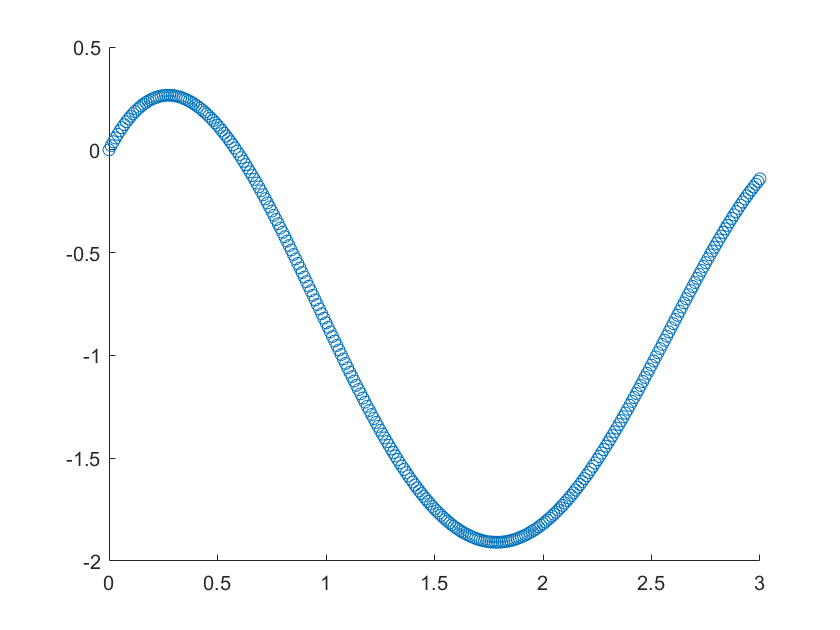

x=0:0.3:3;
y=(x.^2-4.*x+2).*sin(x);
x1=0:0.01:3;
y1=spline(x,y,x1);
scatter(x1,y1)

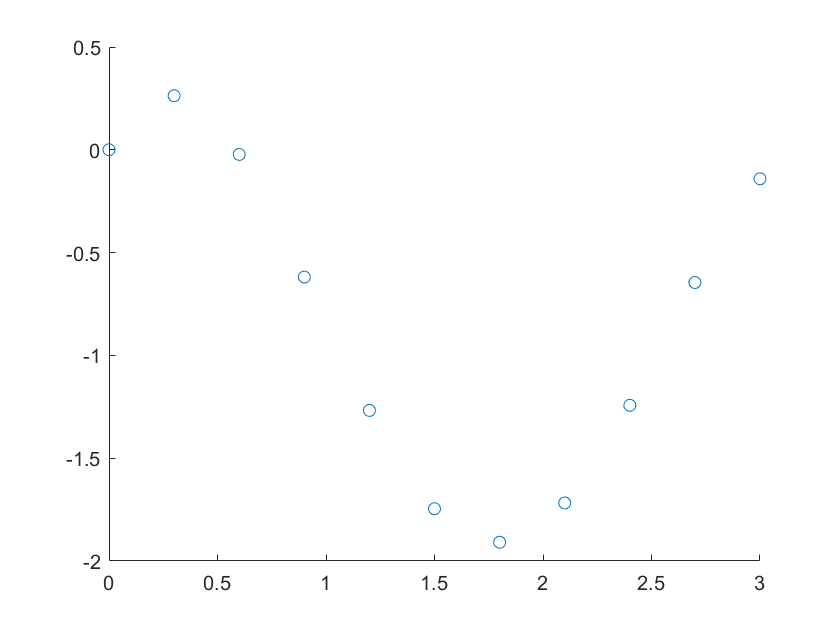

figure
scatter(x,y)

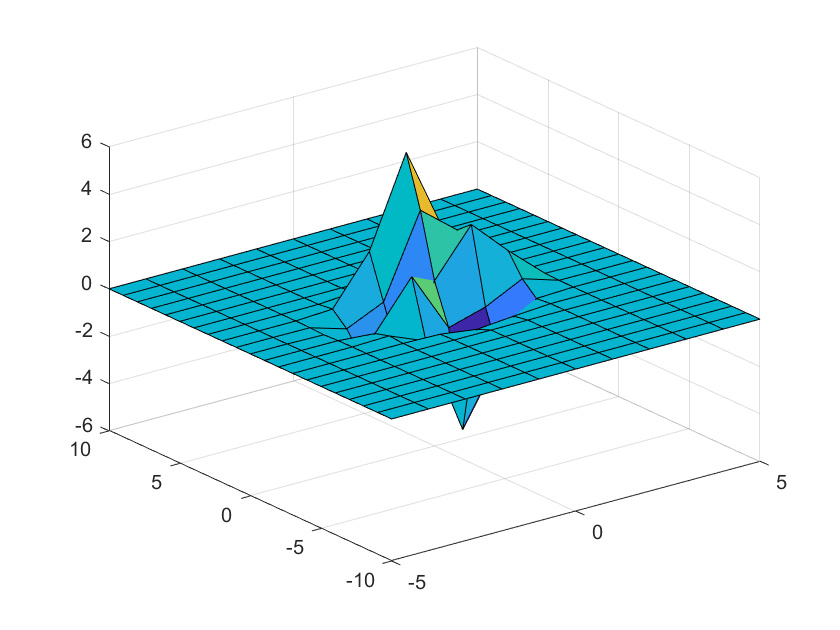

a=-5:5;
b=-10:10;
[a,b]=meshgrid(a,b);
z=peaks(a,b);
surf(a,b,z)

a1=-5:0.2:5;
a2=-10:0.2:10;
[a1,a2]=meshgrid(a1,a2);
a3=interp2(a,b,z,a1,a2,'spline')

a3 =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0009   -0.0012   -0.0010   -0.0006   -0.0000    0.0006    0.0010    0.0011    0.0008   -0.0001   -0.0015   -0.0028   -0.0031   -0.0015    0.0028    0.0115    0.0291    0.0606    0.1114    0.1866    0.2874    0.3997    0.5051    0.5855    0.6226    0.6040    0.5407    0.4492    0.3462    0.2484    0.1692    0.1091    0.0652    0.0349    0.0152    0.0036   -0.0019   -0.0031   -0.0019    0.0002    0.0014    0.0018    0.0016    0.0009    0.0000   -0.0009   -0.0015   -0.0018   -

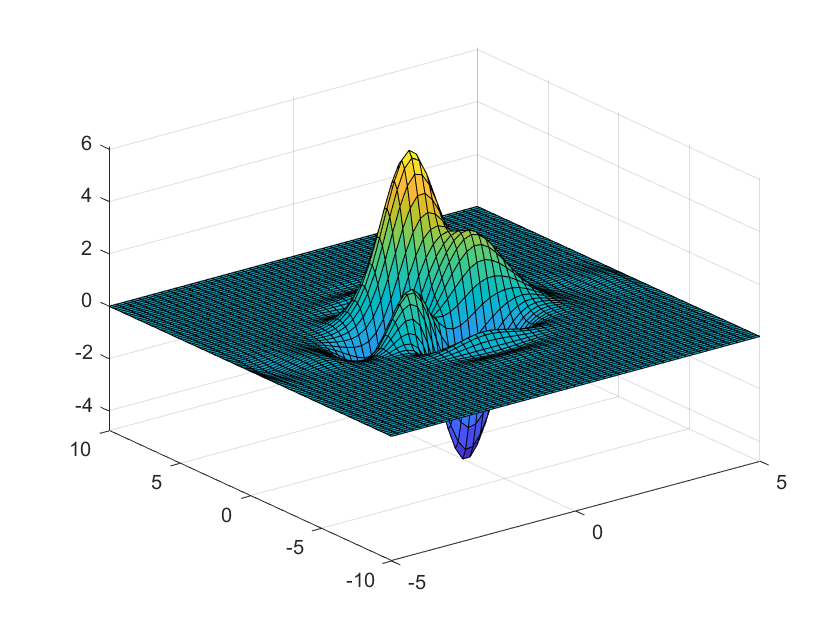

surf(a1,a2,a3)

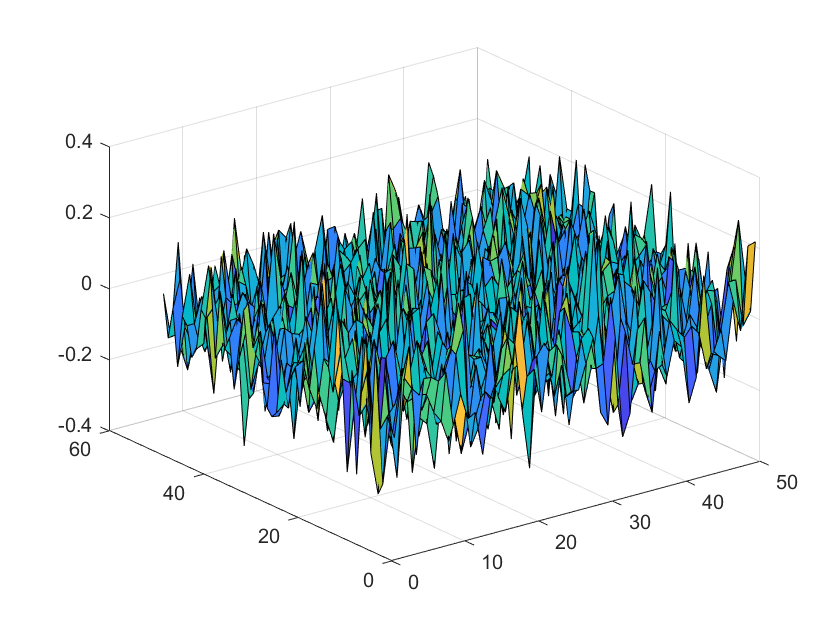

h=normrnd(0,0.1,[50,50]);
surf(h)

z=interp2(h,1,'cubic')

z =    -0.0645    0.0263    0.0976    0.1691    0.1813    0.0179   -0.1298   -0.0444    0.0797    0.0924    0.0770    0.0676    0.0611    0.0801    0.0816   -0.0003   -0.0745   -0.0386    0.0075   -0.0252   -0.0668   -0.0578   -0.0551   -0.1261   -0.1796   -0.1156   -0.0288    0.0006    0.0280    0.1061    0.1630    0.1047    0.0510    0.1429    0.2220    0.1241    0.0066    0.0087    0.0218   -0.0510   -0.1050   -0.0312    0.0603    0.0806    0.0745    0.0586    0.0286   -0.0232   -0.0695   -0.0807
   -0.0584   -0.1097   -0.0961    0.0208    0.1254    0.0672   -0.0111    0.0103    0.0489    0.0565    0.0499    0.0231   -0.0042   -0.0014   -0.0072   -0.0813   -0.1298   -0.0366    0.0723    0.0996    0.0756   -0.0278   -0.1324   -0.1561   -0.1386   -0.0788   -0.0166   -0.0104   -0.0030    0.0650    0.1289    0.1249    0.1098    0.1456    0.1532    0.0393   -0.0916   -0.1638   -0.1834   -0.1067   -0.0078    0.0509    0.0786    0.0424    0.0071    0.0615    0.1008    0.0084   -0.0922   -0

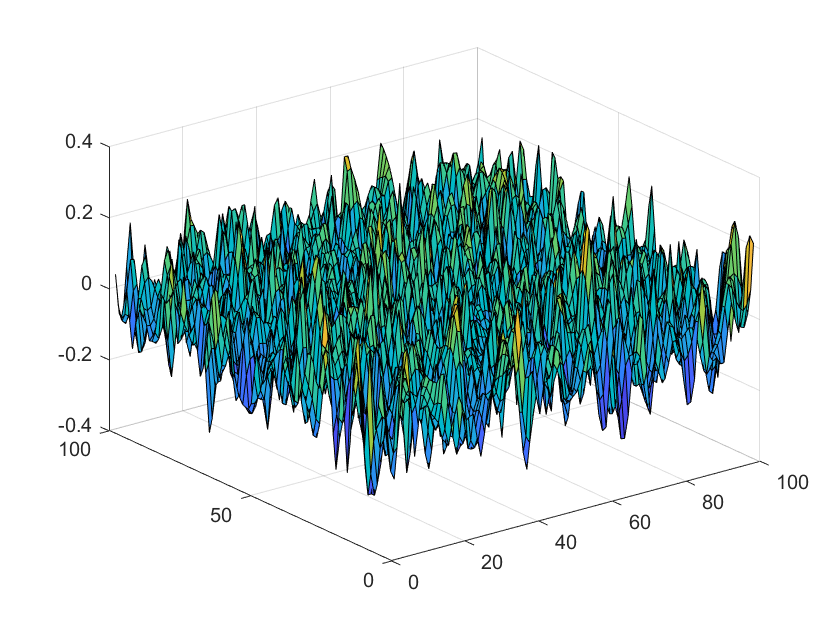

surf(z)

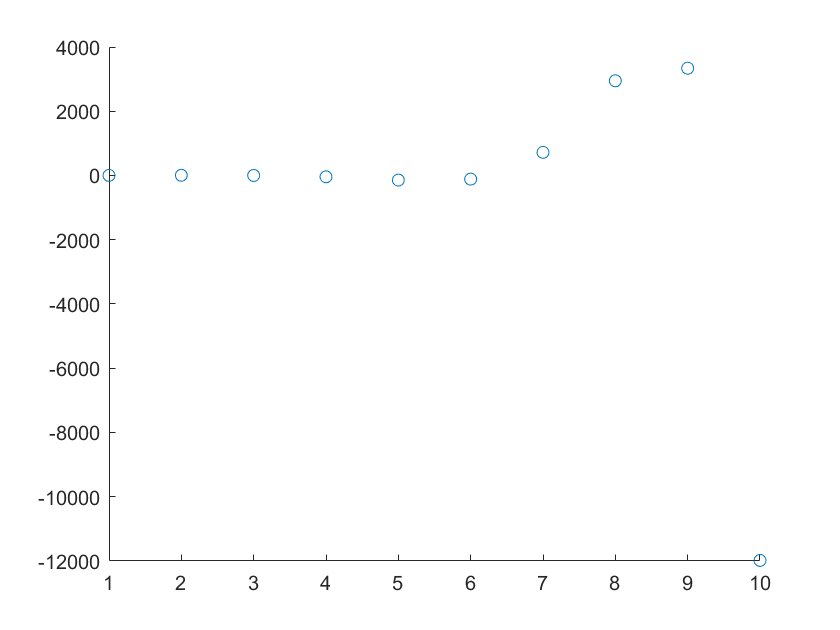

x=1:10;
y=exp(x).*sin(x);
scatter(x,y)

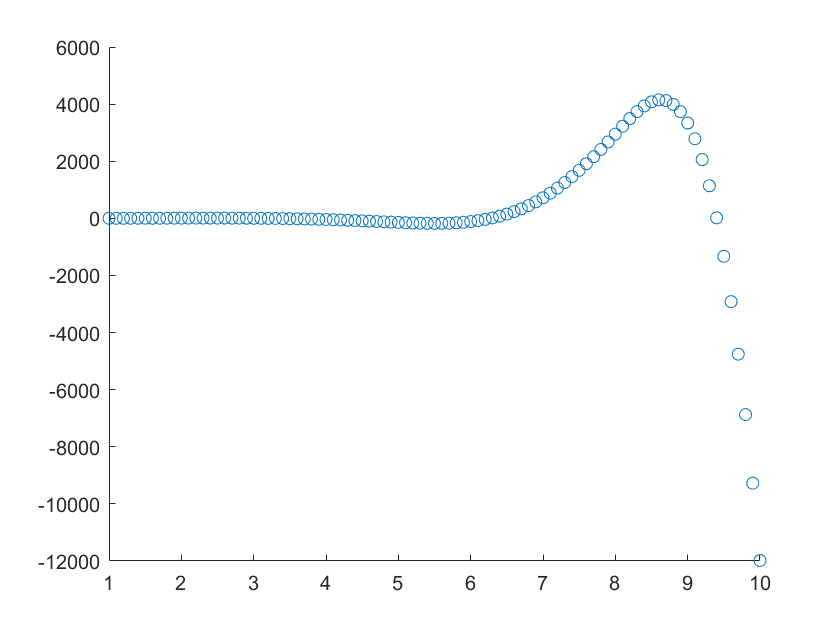

x_new=1:0.1:10;
y_new=spline(x,y,x_new);
scatter(x_new,y_new)

clear all
clear clc
syms x y;
f=2*x+y;
result=diff(f,'y')

$$result = 1$$

class(result)

ans = 'sym'

diff([1,2,3],2)

ans = 0

syms x;
y=-x*sin(x);
result_1=diff(y,2)

$$result\_1 = x\,\sin\left(x\right)-2\,\cos\left(x\right)$$

result_2=diff(y,3)

$$result\_2 = 3\,\sin\left(x\right)+x\,\cos\left(x\right)$$

syms x y z a;
f=x^2-y^2+2*z^2-a^2;
zx=-diff(f,x)/diff(f,y)

$$zx = \frac{x}{y}$$

clear all
clc
syms x y n;
f=(x^(1/n)+y^(1/n))/(x+y);
result=limit(f,x,y,'left')

$$result = y^{\frac{1}{n}-1}$$

class(result)

ans = 'sym'

syms x y;
f=exp(-1/(y^2-x^2));
result=limit(f,x,1/sqrt(y))

$$result = {\mathrm{e}}^{-\frac{y}{y^{3}-1}}$$

result=limit(result,y,Inf)

$$result = 1$$

syms x t;
f=x*t/(1-x^2);
int(f,t)

$$ans = -\frac{t^{2}\,x}{2\,\left(x^{2}-1\right)}$$

g=abs(x+1);
result=int(g,x,2,5);
class(result)

ans = 'sym'

syms x lambda;
f=lambda^x/factorial(x)*(exp(-lambda))

$$f = \frac{\lambda^{x}\,{\mathrm{e}}^{-\lambda }}{x!}$$

int(f,x,0,Inf) %定积分

$$ans = \int_{0}^{\infty }\frac{\lambda^{x}\,{\mathrm{e}}^{-\lambda }}{x!}\mathrm{d}x$$

clear all
clc
syms t x;
f=exp(-t*x)

$$f = {\mathrm{e}}^{-t\,x}$$

a=int(f,t,0,x)

$$a = -\frac{{\mathrm{e}}^{-x^{2}}-1}{x}$$

aa=int(a,x,0,1)

$$aa = \frac{\mathrm{eulergamma}}{2}-\frac{\text{ei}\left(-1\right)}{2}$$

clear all
clc
syms x;
k=6

k = 6

f=(x-1)^3

$$f = {\left(x-1\right)}^{3}$$

taylor(f,x,1)

$$ans = {\left(x-1\right)}^{3}$$

clear all
clc
syms n
gf=1/(n^2);
symsum(gf,n,1,Inf) %级数求和

$$ans = \frac{\pi^{2}}{6}$$